clear
load data2.mat
n=length(data.CzasLokalnyUTC0000);

T=5; %[s]
fs=1/T; %[Hz]
t_all=T*(0:n-1);

Skraplacz=0.1*data.Skraplacz;
Kompresor1=data.Kompresor1;
Parownik1=0.1*data.Parownik1;
Wlot=0.1*data.Wlot;
TemperaturaOtoczenia=0.1*data.TemperaturaOtoczenia;
Rozmraanie=data.Rozmraanie;
WentylatorParownika=data.WentylatorParownika;
ZawrOdszraniania=data.ZawrOdszraniania;

X_all=[ZawrOdszraniania,Kompresor1,WentylatorParownika,Rozmraanie,...
    TemperaturaOtoczenia,Skraplacz,Wlot,Parownik1]';

[X,~]  = GetRidOfNans(X_all);
all_data=length(X)

all_data = 516457

day=24*60*60*fs

day = 17280

t=T*(1:all_data);
X=X';
X=X(:,1:all_data);
size(X)

ans =            8      516457


X_toFilter=X(5:8,:);
threshold=[0,5;0,5;-5,0;-5,0];
for i = 1:4
X_filtered(i,:) = InterpolateData(X_toFilter(i,:),threshold(i,:),t);
end

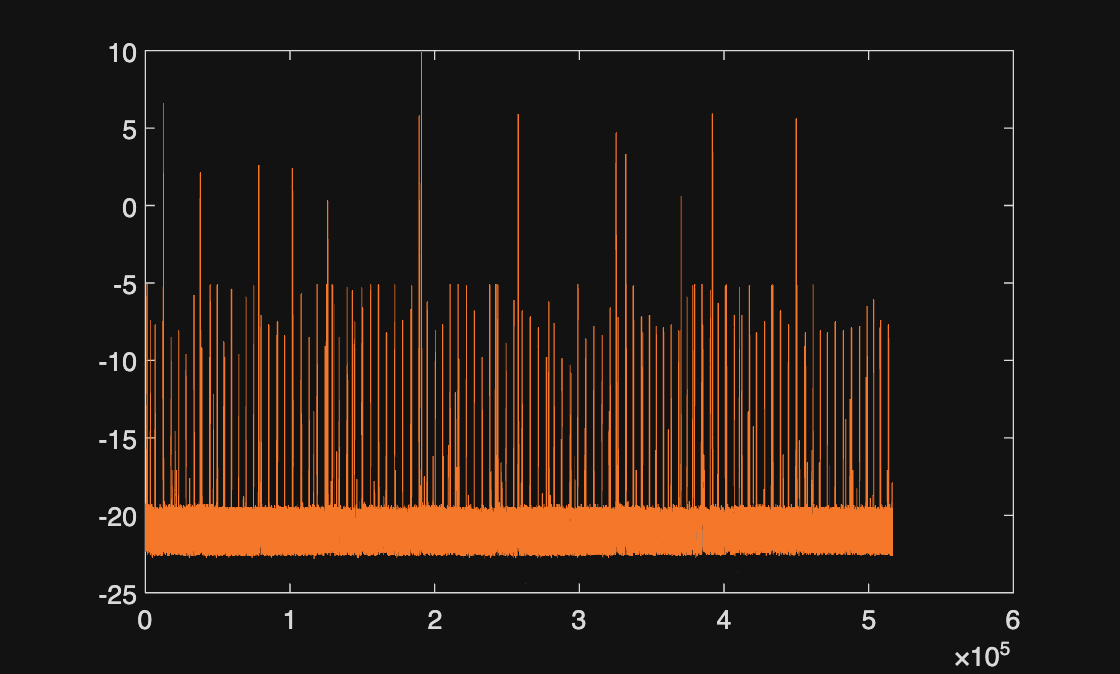

figure
plot(-22.+X(2,:));hold on;
plot(X_filtered(3,:));

We see that there is a temporal shift betwee the temperature peak and compressor turning on

There is a temporal shift between the valley of the temp and the compresor turning off.

Ideally the sfit on the peak would equal the shift of the valley. In this dataset it is pretty close, hence the peak detection algo had better results than the graybox.

The idea here could be:

Assuming we know:

physical parameters like compressor efficiency, tharmal isolation and themral mass (load)

We can:

Run a simulation and get the supposed